**Amelia Rotondo - CWID: 887925113**

# Homework 12 Live Editor Script:

### Problem 2: Chapter 3.1 Problems:

Section 3.1 Problem 3: 

    y = a*(x^b) ---> ln(y) = ln(a) + b*ln(x) 

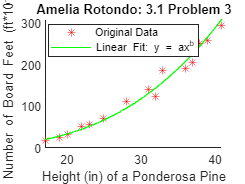

% Data Points
x = [17 19 20 22 23 25 28 31 32 33 36 37 38 39 41];
y = [19 25 32 51 57 71 113 141 123 187 192 205 252 259 294];
xx = min(x):1:max(x);

% Linearize Equation 
X = log(x);
Y = log(y);

% Fit the Linear Model 
AB = polyfit(X, Y, 1);
b = AB(1);
a = exp(AB(2));
yy = a*(xx.^b);

% Calculate R^2
rsq = hwRsq(y, yy);

% Plot Data vs. Fitted Nonlinear Model 
figure(1); clf; hold on;
plot(x, y, 'r*', 'DisplayName', 'Original Data');
plot(xx, yy, 'g', 'DisplayName', 'Linear Fit: y = ax^b');
hold off; 
title('Amelia Rotondo: 3.1 Problem 3');
xlabel('Height (in) of a Ponderosa Pine');
ylabel('Number of Board Feet (ft*10^-1)');
legend('Location', 'best');

fprintf('R-Squared Value: %f\n', rsq);

R-Squared Value: 0.010987


disp('----------------------------');

----------------------------


Section 3.1 Problem 4(a): 

    P = a*(V^b) ---> ln(P) = ln(a) + b*ln(V) 

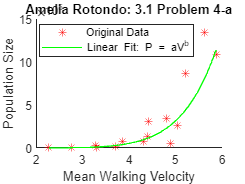

% Data Points 
V1 = [2.27 2.76 3.27 3.31 3.70 3.85 4.31 4.39 4.42];
P1 = [2500 365 23700 5491 14000 78200 70700 138000 304500];
V2 = [4.81 4.90 5.05 5.21 5.62 5.88];
P2 = [341948 49375 260200 867023 1340000 1092759];
x = [V1, V2];
y = [P1, P2];
xx = min(x):0.1:max(x);

% Linearize Equation
X = log(x);
Y = log(y);

% Fit the Linear Model 
AB = polyfit(X, Y, 1);
b = AB(1);
a = exp(AB(2));

yy = a*(xx.^b);

% Calculate R^2
rsq = hwRsq(y, yy);

% Plot Data vs. Fitted Nonlinear Model 
figure(2); clf; hold on;
plot(x, y, 'r*', 'DisplayName', 'Original Data');
plot(xx, yy, 'g', 'DisplayName', 'Linear Fit: P = aV^b');
hold off; 
title('Amelia Rotondo: 3.1 Problem 4-a');
xlabel('Mean Walking Velocity');
ylabel('Population Size');
legend('Location', 'best');

fprintf('R-Squared Value: %f\n', rsq);

R-Squared Value: -0.468907


disp('----------------------------');

----------------------------


Section 3.1 Problem 5(b): 

    P = a*e^(bt) ---> ln(P) = ln(a) + bt 

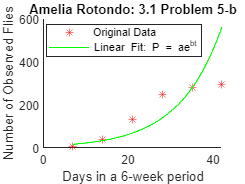

% Data Points 
t = [7 14 21 28 35 42];
P = [8 41 133 250 280 297];
x = t; 
y = P; 
xx = min(x):0.1:max(x);

% Linearize Equation
X = x; 
Y = log(y);

% Fit the Linear Model 
AB = polyfit(X, Y, 1);
b = AB(1);
a = exp(AB(2));
yy = a*exp(b.*xx);

% Calculate R^2
rsq = hwRsq(y, yy);

% Plot Data vs. Fitted Nonlinear Model 
figure(3); clf; hold on;
plot(x, y, 'r*', 'DisplayName', 'Original Data');
plot(xx, yy, 'g', 'DisplayName', 'Linear Fit: P = ae^{bt}');
hold off; 
title('Amelia Rotondo: 3.1 Problem 5-b');
xlabel('Days in a 6-week period');
ylabel('Number of Observed Flies');
legend('Location', 'best');

fprintf('R-Squared Value: %f\n', rsq);

R-Squared Value: -1.720330


disp('----------------------------');

----------------------------


Section 3.1 Problem 6:

    Q = a*e^(bx) ---> ln(Q) = ln(a) + bx 

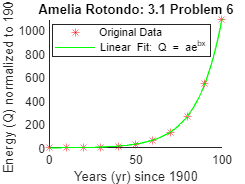

% Data Points 
Q = [1 2.01 4.06 8.17 16.44 33.12 66.69 134.29 270.43 544.57 1096.63];
x = 0:10:100;
y = Q;
xx = min(x):1:max(x);

% Linearize Equation
X = x; 
Y = log(y);

% Fit the Linear Model 
AB = polyfit(X, Y, 1);
b = AB(1);
a = exp(AB(2));
yy = a*exp(b.*xx);

% Calculate R^2
rsq = hwRsq(y, yy);

% Plot Data vs. Fitted Nonlinear Model 
figure(3); clf; hold on;
plot(x, y, 'r*', 'DisplayName', 'Original Data');
plot(xx, yy, 'g', 'DisplayName', 'Linear Fit: Q = ae^{bx}');
hold off; 
title('Amelia Rotondo: 3.1 Problem 6');
xlabel('Years (yr) since 1900');
ylabel('Energy (Q) normalized to 1900');
legend('Location', 'best');

fprintf('R-Squared Value: %f\n', rsq);

R-Squared Value: -0.362863


disp('----------------------------');

----------------------------


Section 3.1 Problem 7:

   T = C*(r^a) ---> ln(T) = ln(C) + a*ln(r) 

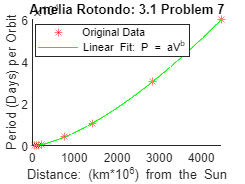

% Data Points 
T = [88 225 365 687 4329 10753 30660 60150];
r = [57.9 108.2 149.6 227.9 778.1 1428.2 2837.9 4488.9];
x = r;
y = T; 
xx = min(x):1:max(x);

% Linearize Equation
X = log(x);
Y = log(y);

% Fit the Linear Model 
AB = polyfit(X, Y, 1);
b = AB(1);
a = exp(AB(2));

yy = a*(xx.^b);

% Calculate R^2
rsq = hwRsq(y, yy);

% Plot Data vs. Fitted Nonlinear Model 
figure(2); clf; hold on;
plot(x, y, 'r*', 'DisplayName', 'Original Data');
plot(xx, yy, 'g', 'DisplayName', 'Linear Fit: P = aV^b');
hold off; 
title('Amelia Rotondo: 3.1 Problem 7');
xlabel('Distance: (km*10^6) from the Sun');
ylabel('Period (Days) per Orbit');
legend('Location', 'best');

fprintf('R-Squared Value: %f\n', rsq);

R-Squared Value: -0.435030


disp('----------------------------');

----------------------------


### Problem 1: On-Lecture Assignment

Function to take the Values of (f(x_i), y_i) from i=1 to N, and return the R^2 value:

NOTE: this is at the bottom of the script to abide by proper matlab function heirarchy syntax.

function [rsq] = hwRsq(ypoints, yfunc)
    
    % Code taken from myRsq to find the R-Squared Value
    ybar = sum(ypoints)/length(ypoints);  % ybar = mean(ypoints)
    SST = 0;
    SSE = 0; 
    for i = 1:length(ypoints)
        SST = SST + (ypoints(i)-ybar)^2;
        SSE = SSE + (yfunc(i) - ypoints(i))^2;
    end
    rsq = 1 - SSE/SST;
end